clear all
L = [3.7/3 3.7/3 3.7/3  0.1 0.1 1.6 0.1 0.1 3.7/3 3.7/3 3.7/3];
R_o = [0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3];

% L = [3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 ...
%      3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 0.1 0.1 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 0.1 0.1 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 ...
%      3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18];
% R_o = [0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 ...
%        0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3];

% L = [3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 ...
%      3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 0.1 0.1 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 0.1 0.1 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 ...
%      3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19];
% R_o = [0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 ...
%        0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3];

E = 200e9;
nu = 0.3;
rho = 7850;
R_i = 0;
pi = 3.1415;
S = pi.*(R_o.^2 - R_i.^2);
I = pi.*(R_o.^4 - R_i.^4)/4;
size_L = size(L);
rho = rho.*[1 1 1 0 0 1 0 0 1 1 1];
% rho = rho.*[1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 1 1 1 1 1 1 1 1 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1];
S = S.*ones(size_L);
E = E.*ones(size_L);
I = I.*ones(size_L);
n = size_L(2) + 1;
S_r = S;
G = E./(2*(1 + nu));
a = (12*E.*I)./(G.*S_r.*L.^2);
M = zeros(n*4);
C = zeros(n*4);
K = zeros(n*4);
for k = 0:n - 2
%     M_0 = [156    0     0      22*L(k+1)   54    0     0       -13*L(k+1);
%        0      156   -22*L(k+1)  0      0     54    13*L(k+1)     0;
%        0     -22*L(k+1)  4*L(k+1)^2  0      0    -13*L(k+1) -3*L(k+1)^2    0;
%        22*L(k+1)   0     0      4*L(k+1)^2  13*L(k+1)  0     0       -3*L(k+1)^2;
%        54     0     0      13*L(k+1)   156   0     0       -22*L(k+1);
%        0      54    -13*L(k+1)  0      0     156   22*L(k+1)     0;
%        0      13*L(k+1) -3*L(k+1)^2  0      0     22*L(k+1)  4*L(k+1)^2    0;
%       -13*L(k+1)   0     0     -3*L(k+1)^2  -22*L(k+1)  0    0        4*L(k+1)^2]*rho(k+1)*S(k+1)*L(k+1)/(420);
    M_ref = [156    0     0     -22*L(1+k)   54    0     0      13*L(1+k);
        0      156   22*L(1+k)   0      0     54   -13*L(1+k)   0;
        0      22*L(1+k)  4*L(1+k)^2  0      0     13*L(1+k) -3*L(1+k)^2  0;
        -22*L(1+k)   0     0      4*L(1+k)^2 -13*L(1+k)  0     0     -3*L(1+k)^2;
        54     0     0     -13*L(1+k)   156   0     0      22*L(1+k);
        0      54    13*L(1+k)   0      0     156  -22*L(1+k)   0;
        0     -13*L(1+k) -3*L(1+k)^2  0      0    -22*L(1+k)  4*L(1+k)^2  0;
        13*L(1+k)   0     0     -3*L(1+k)^2  22*L(1+k)  0     0      4*L(1+k)^2]*rho(k+1)*S(k+1)*L(1+k)/420;

    g1 = 36;
    g2 = -(3 - 15*a(k+1))*L(k+1);
    g3 = (4+5*a(k+1)+10*a(k+1)^2)*L(k+1)^2;
    g4 = (-1 -5*a(k+1) + 5*a(k+1)^2)*L(k+1)^2;
    G = [0  -g1  g2  0   0  g1  g2  0;
        g1  0    0   g2 -g1 0   0   g2;
        -g2  0    0  -g3  g2 0   0  -g4;
        0  -g2   g3  0   0  g2  g4  0;
        0   g1  -g2  0   0 -g1 -g2  0;
        -g1  0    0  -g2  g1 0   0  -g2;
        -g2  0    0  -g4  g2 0   0  -g3;
        0  -g2   g4  0   0  g2  g3  0];
    C_ref = G;

%     K_C = [12   0    0        -6*L(k+1)      -12     0     0        -6*L(k+1);
%            0    12   6*L(k+1)       0         0     -12    6*L(k+1)       0;
%            0    6*L(k+1) (4+a(k+1))*L(k+1)^2  0         0     -6*L(k+1)  (2-a(k+1))*L(k+1)^2  0;
%           -6*L(k+1)  0    0        (4+a(k+1))*L(k+1)^2  6*L(k+1)    0     0        (2-a(k+1))*L(k+1)^2;
%           -12   0    0         6*L(k+1)       12     0     0         6*L(k+1);
%            0   -12  -6*L(k+1)       0         0      12   -6*L(k+1)       0;
%            0    6*L(k+1) (2-a(k+1))*L(k+1)^2  0         0     -6*L(k+1)  (4+a(k+1))*L(k+1)^2  0;
%           -6*L(k+1)  0    0        (2-a(k+1))*L(k+1)^2  6*L(k+1)    0     0        (4+a(k+1))*L(k+1)^2;]*E(k+1)*I(k+1)/((1+a(k+1))*L(k+1)^3);

    K_C = [12   0    0        -6*L(k+1)      -12     0     0        -6*L(k+1);
        0    12   6*L(k+1)       0         0     -12    6*L(k+1)       0;
        0    6*L(k+1) (4+a(k+1))*L(k+1)^2  0         0     -6*L(k+1)  (2-a(k+1))*L(k+1)^2  0;
        -6*L(k+1)  0    0        (4+a(k+1))*L(k+1)^2  6*L(k+1)    0     0        (2-a(k+1))*L(k+1)^2;
        -12   0    0         6*L(k+1)       12     0     0         6*L(k+1);
        0   -12  -6*L(k+1)       0         0      12   -6*L(k+1)       0;
        0    6*L(k+1) (2-a(k+1))*L(k+1)^2  0         0     -6*L(k+1)  (4+a(k+1))*L(k+1)^2  0;
        -6*L(k+1)  0    0        (2-a(k+1))*L(k+1)^2  6*L(k+1)    0     0        (4+a(k+1))*L(k+1)^2;]*E(k+1)*I(k+1)/((1+a(k+1))*L(k+1)^3);
    if rho(k+1) ~= 0
%         M_s = [36   0    0     -3*L(k+1)   -36   0       0     -3*L(k+1);
%            0    36   3*L(k+1)    0      0   -36      3*L(k+1)    0;
%            0    3*L(k+1)  4*L(k+1)^2  0      0   -3*L(k+1)    -L(k+1)^2    0;
%           -3*L(k+1)  0    0      4*L(k+1)^2  3*L(k+1)  0       0     -L(k+1)^2;
%           -36   0    0      3*L(k+1)    36   0       0      3*L(k+1);
%            0   -36  -3*L(k+1)    0      0    36     -3*L(k+1)    0;
%            0    3*L(k+1) -L(k+1)^2    0      0   -3*L(k+1)     4*L(k+1)^2  0;
%           -3*L(k+1)  0    0     -L(k+1)^2    3*L(k+1)  0       0      4*L(k+1)^2]*rho(k+1)*I(k+1)/(30*L(k+1));
%         N = M_s;

    M_s = [36   0    0     -3*L(k+1)   -36   0       0     -3*L(k+1);
           0    36   3*L(k+1)    0      0   -36      3*L(k+1)    0;
           0    3*L(k+1)  4*L(k+1)^2  0      0   -3*L(k+1)    -L(k+1)^2    0;
          -3*L(k+1)  0    0      4*L(k+1)^2  3*L(k+1)  0       0     -L(k+1)^2;
          -36   0    0      3*L(k+1)    36   0       0      3*L(k+1);
           0   -36  -3*L(k+1)    0      0    36     -3*L(k+1)    0;
           0    3*L(k+1) -L(k+1)^2    0      0   -3*L(k+1)     4*L(k+1)^2  0;
          -3*L(k+1)  0    0     -L(k+1)^2    3*L(k+1)  0       0      4*L(k+1)^2]*rho(k+1)*I(k+1)/(30*L(k+1));
        
        N = M_s;
% 
%         C_disk = zeros(8,8);
%     else
%         Added_Mass = 7850*S(k+1)*L(k+1);
%         I_Dx = 0.25*Added_Mass.*(R_o(k+1).^2-R_i.^2);
%         I_Dy = 0.5*Added_Mass.*(R_o(k+1).^2-R_i.^2);
%         M_s = [Added_Mass 0 0 0;
%                0 Added_Mass 0 0;
%                0 0 I_Dx 0 ;
%                0 0 0 I_Dx];
% 
%         C_disk = [0 0 0 0;
%                   0 0 0 0;
%                   0 0 0 -I_Dy;
%                   0 0 I_Dy 0];
    end
    if 1+k*4 < n*4 - 4
        for i = 0:7
            for j = 0:7
                M(1+k*4+i,1+k*4+j) = M(1+k*4+i,1+k*4+j) + M_ref(1+i,1+j) + N(1+i,1+j);
                C(1+k*4+i,1+k*4+j) = C(1+k*4+i,1+k*4+j) + C_ref(1+i,1+j) ;
                K(1+k*4+i,1+k*4+j) = K(1+k*4+i,1+k*4+j) + K_C(1+i,1+j);
            end
        end
    end
end
n_dis = [5 8];
% n_dis = [21 31];
r_d_more = [1 1.25];
b_d_more = [0.2 0.2];
rho_d = 7850;
D_d_more = r_d_more*2;
V_d_more = b_d_more.*pi.*D_d_more.^2/4;
M_D_more = rho_d.*V_d_more;
I_Dx_more = 0.25*M_D_more.*r_d_more.^2  +  (1/12)*M_D_more.*b_d_more.^2;
I_Dy_more =  0.5*M_D_more.*r_d_more.^2;

I_Dx_vec = zeros(1,n);
I_Dy_vec = zeros(1,n);
r_d_vec = zeros(1,n);
b_d_vec = zeros(1,n);
size_n_dis = size(n_dis);
for i_disk = 1:size_n_dis(2)
    I_Dx_vec(1,n_dis(i_disk)) = I_Dx_more(i_disk);
    I_Dy_vec(1,n_dis(i_disk)) = I_Dy_more(i_disk);
    r_d_vec(1,n_dis(i_disk)) = r_d_more(i_disk);
    D_d_vec = r_d_vec*2;
    b_d_vec(1,n_dis(i_disk)) = b_d_more(i_disk);
    V_d_vec = pi*b_d_vec.*D_d_vec.^2/4;
    M_D_vec = rho_d.*V_d_vec;
end
for p = 1:n
    M_disk = [M_D_vec(p);M_D_vec(p);I_Dx_vec(p);I_Dx_vec(p)].*eye(4);
    for i = 0:3
        for j = 0:3
            M(1+(p-1)*4+i,1+(p-1)*4+j)= M(1+(p-1)*4+i,1+(p-1)*4+j) + M_disk(1+i,1+j);
        end
    end
end
for k = 0:n
    if 1+k*4 < n*4 - 4
        C_disk = [0 0 0             0;
                  0 0 0             0;
                  0 0 0            -I_Dy_vec(k+1);
                  0 0 I_Dy_vec(k+1) 0];
        
        for i = 0:3
            for j = 0:3
                C(1+k*4+i,1+k*4+j)= C(1+k*4+i,1+k*4+j) + C_disk(1+i,1+j);
            end
        end
    end
end
%============== BEARINGS AND SEALS ================
speed_in = 4000; % RPM
[kxx(1) ,kxz(1) ,kzx(1) ,kzz(1) ,cxx(1) ,cxz(1) ,czx(1) ,czz(1)]= turb(speed_in);
[kxx(2) ,kxz(2) ,kzx(2) ,kzz(2) ,cxx(2) ,cxz(2) ,czx(2) ,czz(2)]= comp(speed_in);

[C, K] = bearings(kxx ,kxz ,kzx ,kzz ,cxx ,cxz ,czx ,czz ,n ,C, K);

syms omega
assume(omega,'real')
C = C*omega;
[A,B] = matrix(M,C,K,n);

clear w F F_unsorted

A_num = vpa(A,5);
B_num = vpa(B,5);
omega = speed_in*2*pi/60;
A_num_new = subs(A_num,'omega',omega);
% [V_new,D_new]=eigs(pinv(A_num_new)*(B_num));
[V_new,D_new]=eig(lsqminnorm(double(A_num_new),double(B_num)));
w_sorted = sort(imag(diag(D_new)),'ascend');
w(:,1) = w_sorted;
F = w./(2*pi);
F(n*4:n*4.5)

ans =          0
         0
         0
         0
    0.0000
    9.0861
    9.6815


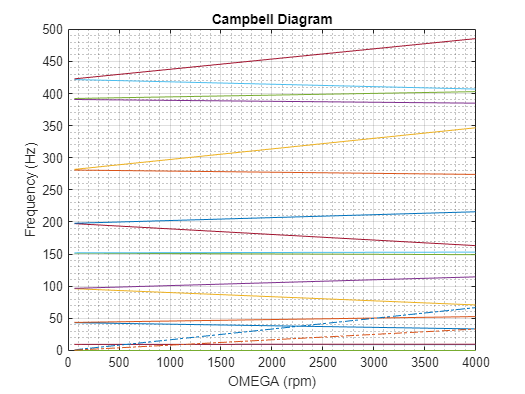

clear w F F_unsorted
i = 1;
for speed = [60, 4000]  % in rad/s

    [kxx(1) ,kxz(1) ,kzx(1) ,kzz(1) ,cxx(1) ,cxz(1) ,czx(1) ,czz(1)]= turb(speed);
    [kxx(2) ,kxz(2) ,kzx(2) ,kzz(2) ,cxx(2) ,cxz(2) ,czx(2) ,czz(2)]= comp(speed);
    [C_new, K_new] = bearings(kxx ,kxz ,kzx ,kzz ,cxx ,cxz ,czx ,czz ,n ,C, K);
    omega = speed*2*pi/60;
    [A,B] = matrix(M,C_new,K_new,n);
    A_num = vpa(A,5);
    B_num = vpa(B,5);
    A_num_new = subs(A_num,'omega',omega);
    [V_new,D_new]=eig(lsqminnorm(double(A_num_new),double(B_num)));

    [w_sorted,ind] = sort(imag(diag(D_new)),'ascend');
    F_unsorted(:,i) = imag(diag(D_new))./(2*pi);
    w(:,i) = w_sorted;
    i = i+1;
    F = w./(2*pi);
    if omega == 60*2*pi/60
        V_new_sorted = V_new(:,ind);
    else
        V_new_sorted2 = V_new(:,ind);
    end
end
% [eigvector, eigvalue]=eig(A - (lan).*B)

omega= [60,4000];
plot(omega,F(n*4:n*4+20,:))        % Colision With y-axis (F) verified using (F0 = nat_freq/2pi)
grid on
grid minor
hold on 
plot(omega,omega/60, '-.')
plot(omega,0.5*omega/60, '-.')
title('Campbell Diagram')
xlabel('OMEGA (rpm)')
ylabel('Frequency (Hz)')
hold off

F(n*4:n*4+20,:)

ans =          0         0
         0         0
         0         0
         0         0
         0    0.0000
    9.4025    9.0862
    9.5291    9.6817
   43.2352   33.5430
   43.6472   52.7615
   96.1629   70.8857



% omega= [60,4000];
% plot(omega,F_unsorted)        % Colision With y-axis (F) verified using (F0 = nat_freq/2pi)
% grid on
% grid minor
% hold on 
% plot(omega,omega/60, '-.')
% plot(omega,0.5*omega/60, '-.')
% title('Campbell Diagram')
% xlabel('OMEGA (rpm)')
% ylabel('Frequency (Hz)')
% hold off

syms x
y1(x) = x/60;
num = 1;
for i = n*4:n*8
    y2(x) = ((F(i,2)-F(i,1))/(4000-60))*(x - 60) + F(i,1);
    if vpasolve(y1 == y2) ~= 0
        crit_speed(num) = vpasolve(y1 == y2);
    end
    num = num+1;
end
crit_speed'

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ -0.00000000000010799096616840171076271891528394\\ 561.73574745652574195684761515276\\ 572.93705256668575996828676910383\\ 2268.1890285948678725067642308172\\ 3031.2252677594337879302214594013\\ 4182.7834083196917118871823302611\\ 7949.9607148191678654708264963312\\ 8783.1179814864314446216914850689\\ 9272.8556820092076456526554124292\\ 7809.4281824399036353931012170042\\ 16306.58297237760687212945280784\\ 15274.857800511696781701105359089\\ 1196938.5201719688796903742940324\\ 21567.99125994161290201566386474\\ 28082.947814371275597299952249345\\ 20671.124424257043216691432619681\\ 535118.79828272241750351359329963\\ 56004.441325198778346975047234634\\ 57274.466612076886349732212823497\\ 64080.863339826109503420515855257\\ 70068.767859298575914080288507529\\ 44120.807121078950941157679217941\\ 216646.29451419743666531325514733\\ 125629.6098538016039069468402495\\ 145506.4951591075018470922453175\\ 248027.07183116480780073635078951\\ 387245.37957539248420396140365884\\ 76718.757481931589055634195012925\\ -69873412.743777654782098727048122\\ -1368867.2882343998962759889279431\\ -321007.1195993227300227164550859\\ -123846.01870349848873061489287836\\ -72458.903935956706906221653376345\\ -37305.369638521026435802183407277\\ -38680.117523235372057924372850827\\ -34097.935960190403610049666584952\\ -34496.697678652223951652321180821\\ 58274.800228223225940012956196146\\ -200476.1967622615860979045652766\\ 42478.25155236066364701769985564\\ 43411.99191115219847835895018045\\ 35259.809162661145987929051125775\\ -58407.969703208859206837720551425\\ -33442.721111850628140529855421124\\ -33766.294463685917779151227249721 \end{array}\right)$$

syms x
y1(x) = 0.5*x/60;
num = 1;
for i = n*4:n*8
    y2(x) = ((F(i,2)-F(i,1))/(4000-60))*(x - 60) + F(i,1);
    if vpasolve(y1 == y2) ~= 0
        crit_speed_half(num) = vpasolve(y1 == y2);
    end
    num = num+1;
end
crit_speed_half'

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ -0.00000000000021598193233680381026039696339801\\ 1118.1116083835916918069188871676\\ 1148.5500689520298203077644337962\\ 4019.4254207906324861931462447678\\ 7227.2261683069981759489184041575\\ 6546.1202914396397879678823278286\\ 25392.038882145418270105376433357\\ 16998.463639632967956561215906508\\ 18862.146517926482307019002075478\\ 11634.345031641489406949000946304\\ 52132.386002828195981771526727896\\ 27928.674229030416802237312795078\\ -34683.336952622894119989738420504\\ 39936.552213662417483315923711635\\ 69663.923872976493504710796739312\\ 34932.146988597200179474623833112\\ -55915.867325498515884636247437198\\ 117866.80056318045988775424944128\\ 122090.04662658257627863486819341\\ 157650.54249076058280258156630499\\ 196326.03529201178253640171533802\\ 62997.95676826742987476571266547\\ -459238.52533575345971136291330299\\ 487231.0355833891617257942238487\\ 978648.77960008577914455555201673\\ -554429.10981072383687713568992492\\ -311836.04619250568716126850923548\\ 110559.02113024737083891236178675\\ -251219.90241213893172689651906331\\ -217396.08649459391606487592346815\\ -144076.88393957766288148914298911\\ -84428.47317379441968671183081267\\ -56978.423365165684781954228429691\\ -33269.543712921108756714456638602\\ -34374.537137180857459557536243131\\ -30718.752790335569532267847756588\\ -31050.390181733191950864770701621\\ 65657.366785331636873647731331327\\ -144572.42946379127840499360204232\\ 45732.79805427381357225028284923\\ 46804.695439420226515166179661007\\ 37385.952846716974303844525812099\\ -53383.643728743721462507464861568\\ -31733.900879812012696337111633981\\ -32030.979277744788186974091260771 \end{array}\right)$$

function [K11_fit_t ,K12_fit_t ,K21_fit_t ,K22_fit_t ,D11_fit_t ,D12_fit_t ,D21_fit_t ,D22_fit_t] = turb(speed_in)
method = 'cubicinterp';
speed_t = [367.8893038, 594.9139299, 964.0472719, 1495.62474, 2253.969678, 3272.634911, 6452.897062, 10064.89605, 14548.34974, 54432.60107];
K11_t = [1.96E+09, 1.31E+09, 9.07E+08, 7.03E+08, 5.52E+08, 4.67E+08, 4.23E+08, 4.75E+08, 5.55E+08, 1.24E+09];
K12_t = [2.69E+09, 1.69E+09, 1.08E+09, 6.90E+08, 3.55E+08, 1.98E+08, -2.94E+08, -8.76E+08, -1.59E+09, -6.98E+09];
K21_t = [7.65E+09, 5.18E+09, 3.64E+09, 2.83E+09, 2.26E+09, 1.95E+09, 1.74E+09, 1.75E+09, 2.03E+09, 5.57E+09];
K22_t = [2.42E+10, 1.54E+10, 1.04E+10, 7.46E+09, 5.43E+09, 4.52E+09, 3.75E+09, 4.13E+09, 5.16E+09, 1.69E+10];
D11_t = [1.12E+07, 4.66E+06, 2.23E+06, 1.55E+06, 1.11E+06, 8.13E+05, 7.18E+05, 6.98E+05, 6.89E+05, 5.73E+05];
D12_t = [2.89E+07, 9.77E+06, 3.49E+06, 2.07E+06, 1.01E+06, 2.62E+05, -3.17E+05, -6.29E+05, -8.34E+05, -1.03E+06];
D21_t = [2.80E+07, 9.30E+06, 3.27E+06, 2.03E+06, 1.08E+06, 2.93E+05, -3.19E+05, -6.32E+05, -8.38E+05, -1.04E+06];
D22_t = [2.51E+08, 1.08E+08, 4.91E+07, 2.75E+07, 1.65E+07, 1.02E+07, 5.80E+06, 4.69E+06, 4.47E+06, 4.26E+06];
K11_fit_t = fit(speed_t',K11_t',method);
K12_fit_t = fit(speed_t',K12_t',method);
K21_fit_t = fit(speed_t',K21_t',method);
K22_fit_t = fit(speed_t',K22_t',method);
D11_fit_t = fit(speed_t',D11_t',method);
D12_fit_t = fit(speed_t',D12_t',method);
D21_fit_t = fit(speed_t',D21_t',method);
D22_fit_t = fit(speed_t',D22_t',method);
if speed_in < speed_t(1)
    K11_fit_t = K11_t(1);
    K12_fit_t = K12_t(1);
    K21_fit_t = K21_t(1);
    K22_fit_t = K22_t(1);
    D11_fit_t = D11_t(1);
    D12_fit_t = D12_t(1);
    D21_fit_t = D21_t(1);
    D22_fit_t = D22_t(1);
elseif speed_in > speed_t(end)
    K11_fit_t = K11_t(end);
    K12_fit_t = K12_t(end);
    K21_fit_t = K21_t(end);
    K22_fit_t = K22_t(end);
    D11_fit_t = D11_t(end);
    D12_fit_t = D12_t(end);
    D21_fit_t = D21_t(end);
    D22_fit_t = D22_t(end);
else
    K11_fit_t = K11_fit_t(speed_in);
    K12_fit_t = K12_fit_t(speed_in);
    K21_fit_t = K21_fit_t(speed_in);
    K22_fit_t = K22_fit_t(speed_in);
    D11_fit_t = D11_fit_t(speed_in);
    D12_fit_t = D12_fit_t(speed_in);
    D21_fit_t = D21_fit_t(speed_in);
    D22_fit_t = D22_fit_t(speed_in);
end
end
function [K11_fit_c ,K12_fit_c ,K21_fit_c ,K22_fit_c ,D11_fit_c ,D12_fit_c ,D21_fit_c ,D22_fit_c] = comp(speed_in)
method = 'cubicinterp';
speed_c = [387.2429791, 626.2107655, 1014.763228, 1574.305569, 2372.545013, 3444.799508, 6792.366771, 10594.38339, 15313.69963, 57296.15507];
K11_c = [1.86E+09, 1.24E+09, 8.60E+08, 6.66E+08, 5.23E+08, 4.42E+08, 4.01E+08, 4.50E+08, 5.26E+08, 1.18E+09];
K12_c = [2.55E+09, 1.60E+09, 1.03E+09, 6.54E+08, 3.36E+08, 1.88E+08, -2.78E+08, -8.30E+08, -1.51E+09, -6.61E+09];
K21_c = [7.25E+09, 4.90E+09, 3.45E+09, 2.68E+09, 2.14E+09, 1.85E+09, 1.65E+09, 1.66E+09, 1.92E+09, 5.27E+09];
K22_c = [2.29E+10, 1.46E+10, 9.85E+09, 7.07E+09, 5.15E+09, 4.28E+09, 3.55E+09, 3.91E+09, 4.88E+09, 1.61E+10];
D11_c = [1.01E+07, 4.19E+06, 2.00E+06, 1.39E+06, 1.00E+06, 7.31E+05, 6.46E+05, 6.28E+05, 6.20E+05, 5.15E+05];
D12_c = [2.61E+07, 8.79E+06, 3.14E+06, 1.86E+06, 9.12E+05, 2.36E+05, -2.86E+05, -5.66E+05, -7.51E+05, -9.29E+05];
D21_c = [2.52E+07, 8.37E+06, 2.94E+06, 1.83E+06, 9.71E+05, 2.64E+05, -2.87E+05, -5.69E+05, -7.54E+05, -9.32E+05];
D22_c = [2.26E+08, 9.69E+07, 4.42E+07, 2.47E+07, 1.48E+07, 9.22E+06, 5.22E+06, 4.22E+06, 4.02E+06, 3.83E+06];
K11_fit_c = fit(speed_c',K11_c',method);
K12_fit_c = fit(speed_c',K12_c',method);
K21_fit_c = fit(speed_c',K21_c',method);
K22_fit_c = fit(speed_c',K22_c',method);
D11_fit_c = fit(speed_c',D11_c',method);
D12_fit_c = fit(speed_c',D12_c',method);
D21_fit_c = fit(speed_c',D21_c',method);
D22_fit_c = fit(speed_c',D22_c',method);
if speed_in < speed_c(1)
    K11_fit_c = K11_c(1);
    K12_fit_c = K12_c(1);
    K21_fit_c = K21_c(1);
    K22_fit_c = K22_c(1);
    D11_fit_c = D11_c(1);
    D12_fit_c = D12_c(1);
    D21_fit_c = D21_c(1);
    D22_fit_c = D22_c(1);
elseif speed_in > speed_c(end)
    K11_fit_c = K11_c(end);
    K12_fit_c = K12_c(end);
    K21_fit_c = K21_c(end);
    K22_fit_c = K22_c(end);
    D11_fit_c = D11_c(end);
    D12_fit_c = D12_c(end);
    D21_fit_c = D21_c(end);
    D22_fit_c = D22_c(end);
else
    K11_fit_c = K11_fit_c(speed_in);
    K12_fit_c = K12_fit_c(speed_in);
    K21_fit_c = K21_fit_c(speed_in);
    K22_fit_c = K22_fit_c(speed_in);
    D11_fit_c = D11_fit_c(speed_in);
    D12_fit_c = D12_fit_c(speed_in);
    D21_fit_c = D21_fit_c(speed_in);
    D22_fit_c = D22_fit_c(speed_in);
end
end
function [C_new, K_new] = bearings(kxx ,kxz ,kzx ,kzz ,cxx ,cxz ,czx ,czz ,n ,C, K)
C_new = C;
K_new = K;
n_bearings = [1 n];
size_n_bear = size(n_bearings);
for bearing = n_bearings
    k = bearing - 1;
    %     if 1+k*4 < n*4
    if k ~= n - 1
        K_bearing =-[kxx(size_n_bear(1))  kxz(size_n_bear(1)) 0 0;
            kzx(size_n_bear(1))  kzz(size_n_bear(1)) 0 0;
            0   0 0   0;
            0   0 0   0];
    else
        K_bearing =-[kxx(size_n_bear(2))  kxz(size_n_bear(2)) 0 0;
            kzx(size_n_bear(2))  kzz(size_n_bear(2)) 0 0;
            0   0 0   0;
            0   0 0   0];
    end
    for i = 0:3
        for j = 0:3
            K_new(1+k*4+i,1+k*4+j)= K(1+k*4+i,1+k*4+j) + K_bearing(1+i,1+j);
        end
    end
    %     end
    k = bearing - 1;
    %     if 1+k*4 < n*4
    if k ~= n - 1
        C_bearing =-[cxx(size_n_bear(1))  cxz(size_n_bear(1)) 0 0;
            czx(size_n_bear(1))  czz(size_n_bear(1)) 0 0;
            0   0 0   0;
            0   0 0   0];
    else
        C_bearing =-[cxx(size_n_bear(2))  cxz(size_n_bear(2)) 0 0;
            czx(size_n_bear(2))  czz(size_n_bear(2)) 0 0;
            0   0 0   0;
            0   0 0   0];
    end

    for i = 0:3
        for j = 0:3
            C_new(1+k*4+i,1+k*4+j)= C(1+k*4+i,1+k*4+j) + C_bearing(1+i,1+j);
        end
    end
    %     end
end
end
function [A,B] = matrix(M,C,K,n)
A = [zeros(n*4)  M;M  C];
B = [M  zeros(n*4);zeros(n*4)  -K];
end
